Cargar conjuntos de datos

% Fijar semilla para reproducibilidad
rng(7);

% Cargar la serie completa de Henon
load('D:/MUBICS/Inteligencia_Computacional/Practicas/P3/Henon/Henon.mat');  % La variable 'x' contiene 300000 muestras

% Seleccionar una posición aleatoria de inicio
N_total = length(x);      % Total de muestras disponibles
N = 1500;                 % Número de muestras a extraer
start_idx = randi([1, N_total - N + 1]);  % Índice de inicio aleatorio

% Seleccionar 1500 muestras consecutivas desde la posición aleatoria
x = x(start_idx : start_idx + N - 1);

summary(x)


x: 1500×1 double

    NumMissing            0  
    Min             -1.2847  
    Median           0.4095  
    Max              1.2729  
    Mean             0.2578  
    Std              0.7207  



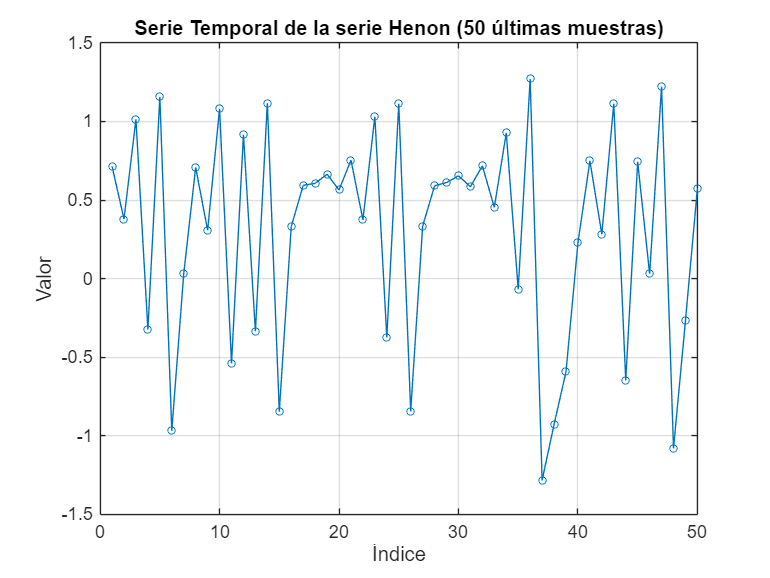

% Tomar las 50 últimas muestras
x_last50 = x(end-49:end);

% Crear gráfico de puntos unidos por líneas (50 últimas muestras)
figure;
plot(x_last50, '-o', 'MarkerSize', 4);
title('Serie Temporal de la serie Henon (50 últimas muestras)');
xlabel('Índice');
ylabel('Valor');
grid on;

Generar 2 conjuntos de datos con distinto tamaño de ventana

% Tamaños de las ventanas
d1 = 5;
d2 = 10;

% Aplicamos la función slidingwindow para cada tamaño de ventana
[INPUTS1, OUTPUTS1] = slidingwindow(x, d1);
[INPUTS2, OUTPUTS2] = slidingwindow(x, d2);

% Mostramos las dimensiones para verificar
disp("Conjunto 1:");

Conjunto 1:


disp(size(INPUTS1));

        1495           5



disp(size(OUTPUTS1));

        1495           1




disp("Conjunto 2:");

Conjunto 2:


disp(size(INPUTS2)) 

        1490          10



disp(size(OUTPUTS2))

        1490           1



Entrenamiento de las NNs para el primer conjunto de datos con tamaño de ventana 5  (k-fold cross validation, MSE/RMSE/MAE)

function [metricsNN, combinaciones] = get_metricsNN(INPUTS, OUTPUTS, neuronas, algoritmos, number_reps, K)
    [N, A] = ndgrid(neuronas, 1:length(algoritmos));
    combinaciones = [N(:), A(:)];
    numComb = size(combinaciones, 1);

    metricsNN = struct('MSE', zeros(K, numComb, number_reps), ...
                       'RMSE', zeros(K, numComb, number_reps), ...
                       'MAE', zeros(K, numComb, number_reps));

    for modelIdx = 1:numComb
        n = combinaciones(modelIdx, 1);
        algIdx = combinaciones(modelIdx, 2);
        alg = algoritmos{algIdx};

        for rep = 1:number_reps
            cv = cvpartition(size(INPUTS,1), 'KFold', K);

            for fold = 1:K
                idxTrain = training(cv, fold);
                idxTest = test(cv, fold);

                X_train = INPUTS(idxTrain, :);
                Y_train = OUTPUTS(idxTrain);
                X_test = INPUTS(idxTest, :);
                Y_test = OUTPUTS(idxTest);

                net = fitnet(n, alg);
                net.trainParam.showWindow = false;
                net.divideParam.trainRatio = 0.8;
                net.divideParam.valRatio = 0.2;
                net.divideParam.testRatio = 0;

                net = train(net, X_train', Y_train');

                Y_pred = net(X_test')';

                metricsNN.MSE(fold, modelIdx, rep) = mean((Y_test - Y_pred).^2);
                metricsNN.RMSE(fold, modelIdx, rep) = sqrt(mean((Y_test - Y_pred).^2));
                metricsNN.MAE(fold, modelIdx, rep) = mean(abs(Y_test - Y_pred));
            end
        end
    end
end



Entrenamos modelo con ventana tamaño 5

% Hiperparámetros
neuronas = [5, 10, 15];
algoritmos = {'trainscg', 'trainlm'};
reps = 3;
K = 10;

[metricsNN_DATOS1, combinacionesNN] = get_metricsNN(INPUTS1, OUTPUTS1, neuronas, algoritmos, reps, K);

% Promediar sobre folds y repeticiones para Redes Neuronales
Mean_MSE_final_NN = squeeze(mean(mean(metricsNN_DATOS1.MSE, 1), 3));
Std_MSE_final_NN  = squeeze(std(reshape(metricsNN_DATOS1.MSE, K*reps, []), 0, 1));

Mean_RMSE_final_NN = squeeze(mean(mean(metricsNN_DATOS1.RMSE, 1), 3));
Std_RMSE_final_NN  = squeeze(std(reshape(metricsNN_DATOS1.RMSE, K*reps, []), 0, 1));

Mean_MAE_final_NN = squeeze(mean(mean(metricsNN_DATOS1.MAE, 1), 3));
Std_MAE_final_NN  = squeeze(std(reshape(metricsNN_DATOS1.MAE, K*reps, []), 0, 1));


function mostrarResumenNN_Regresion(combinaciones, algoritmos, ...
    Mean_MSE, Std_MSE, ...
    Mean_RMSE, Std_RMSE, ...
    Mean_MAE, Std_MAE)

    numCombinaciones = size(combinaciones, 1);

    modelo = strings(numCombinaciones, 1);
    algoritmo = strings(numCombinaciones, 1);
    neuronas = zeros(numCombinaciones, 1);

    for i = 1:numCombinaciones
        neuronas(i) = combinaciones(i, 1);
        algoritmo(i) = algoritmos{combinaciones(i, 2)};
        modelo(i) = sprintf("NN %d", i);
    end

    tabla = table(modelo, neuronas, algoritmo, ...
        Mean_MSE(:), Std_MSE(:), ...
        Mean_RMSE(:), Std_RMSE(:), ...
        Mean_MAE(:), Std_MAE(:), ...
        'VariableNames', {'Modelo', 'Neuronas', 'Algoritmo', ...
        'MSE', 'MSE_std', 'RMSE', 'RMSE_std', 'MAE', 'MAE_std'});

    disp(tabla);
end


mostrarResumenNN_Regresion(combinacionesNN, algoritmos, ...
    Mean_MSE_final_NN, Std_MSE_final_NN, ...
    Mean_RMSE_final_NN, Std_RMSE_final_NN, ...
    Mean_MAE_final_NN, Std_MAE_final_NN);

    Modelo    Neuronas    Algoritmo        MSE         MSE_std         RMSE        RMSE_std        MAE         MAE_std  
    ______    ________    __________    __________    __________    __________    __________    __________    __________

    "NN 1"        5       "trainscg"     0.0086434     0.0014148       0.04776      0.017911      0.035762      0.014306
    "NN 2"       10       "trainscg"    0.00077211    0.00011815      0.023707     0.0046314      0.018715     0.0032482
    "NN 3"       15       "trainscg"    0.00059069    0.00086422      0.022333      0.012925      0.017243     0.0096826
    "NN 4"        5       "trainlm"     2.1606e-05     1.387e-08    0.00097319    5.4797

Comparaciones múltiples entre NNs para el primer conjunto de datos con tamaño de ventana 5

% Almacenar las métricas para la primera repetición (rep = 1)
metricsNN_DATOS1_1 = struct( ...
    'MSE', metricsNN.MSE(:,:,1), ...
    'RMSE', metricsNN.RMSE(:,:,1), ...
    'MAE', metricsNN.MAE(:,:,1));


Test de ANOVA para MSE


P-valor: 0.1878


No se encontraron diferencias significativas entre las configuraciones de NN para MSE.



Test de ANOVA para RMSE


P-valor: 0.0000


Se encontraron diferencias significativas entre las configuraciones de NN. Realizando comparaciones múltiples...


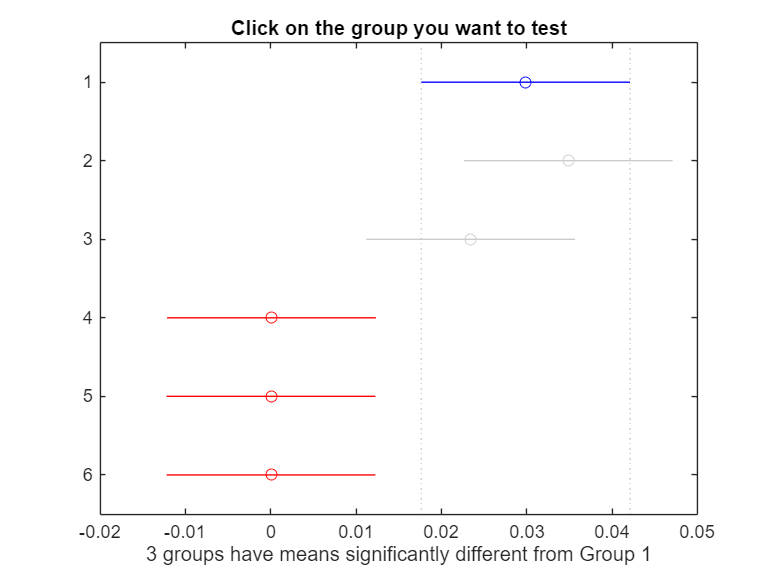

    Grupo1    Grupo2     Lower_CI        Diff       Upper_CI      PValue  
    ______    ______    __________    __________    ________    __________

      1         2        -0.029461    -0.0049956     0.01947             1
      1         3        -0.018026     0.0064397    0.030905             1
      1         4        0.0053259      0.029791    0.054257     0.0066999
      1         5        0.0053732      0.029839    0.054304     0.0065757
      1         6        0.0053756      0.029841    0.054306     0.0065694
      2         3         -0.01303      0.011435    0.035901             1
      2         4         0.010322      0.034787    0.059252    0.00086109
      2         5         0.010369      0.034834      0.0593    0.00084401
      2         6         0.010371      0.034


Test de ANOVA para MAE


P-valor: 0.0000


Se encontraron diferencias significativas entre las configuraciones de NN. Realizando comparaciones múltiples...


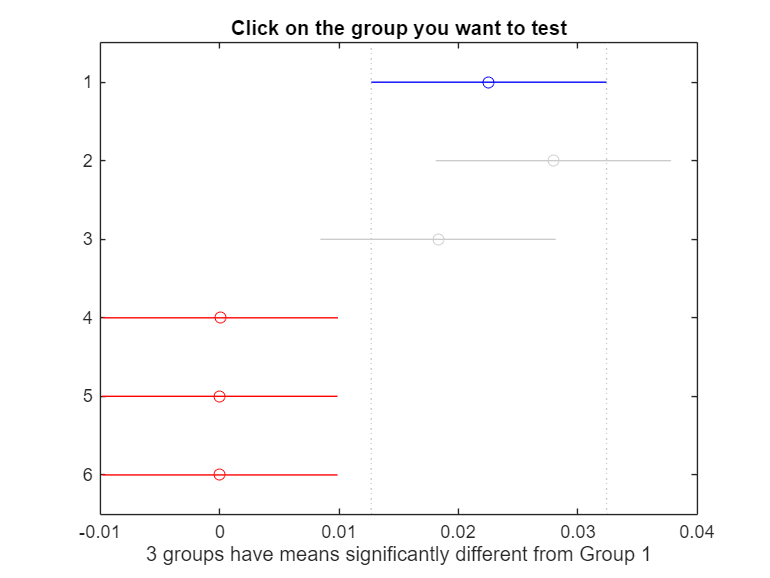

    Grupo1    Grupo2     Lower_CI        Diff       Upper_CI      PValue  
    ______    ______    __________    __________    ________    __________

      1         2        -0.025107    -0.0054056    0.014296             1
      1         3        -0.015446     0.0042553    0.023957             1
      1         4        0.0027799      0.022481    0.042183      0.013909
      1         5        0.0028174      0.022519     0.04222      0.013663
      1         6        0.0028191      0.022521    0.042222      0.013652
      2         3         -0.01004     0.0096609    0.029362             1
      2         4        0.0081856      0.027887    0.047588    0.00092018
      2         5         0.008223      0.027924    0.047626    0.00090222
      2         6        0.0082248      0.027

% Lista de métricas a evaluar
metricNames = {'MSE', 'RMSE', 'MAE'};

% Aplicar ANOVA para cada métrica en Redes Neuronales
for m = 1:numel(metricNames)
    metricName = metricNames{m};

    % Extraer la métrica correspondiente de la primera repetición
    metricData = metricsNN_DATOS1_1.(metricName);  % [folds × modelos]
    numFolds = size(metricData, 1);
    numModels = size(metricData, 2);

    y = metricData(:);  % vector de valores
    group = repelem(1:numModels, numFolds)';  % etiquetas de grupo

    % ANOVA
    [p, ~, stats] = anova1(y, group, 'off');

    % Mostrar resultados
    fprintf('\nTest de ANOVA para %s\n', metricName);
    fprintf('P-valor: %.4f\n', p);

    if p < 0.05
        fprintf('Se encontraron diferencias significativas entre las configuraciones de NN. Realizando comparaciones múltiples...\n');

        figure;
        title(sprintf('Comparaciones múltiples para %s', metricName));
        [c, ~, ~, ~] = multcompare(stats, 'CType', 'bonferroni');

        disp(array2table(c, ...
            'VariableNames', {'Grupo1', 'Grupo2', 'Lower_CI', 'Diff', 'Upper_CI', 'PValue'}));
    else
        fprintf('No se encontraron diferencias significativas entre las configuraciones de NN para %s.\n', metricName);
    end
end

Hay diferencias significativas entre los NN con distintos algoritmos, por lo que el modelo seleccionado sería el NN4 (algoritmo trainlm y nº neuronas 5).

 Entrenamos modelo con ventana tamaño 10

% Hiperparámetros
neuronas = [5, 10, 15];
algoritmos = {'trainscg', 'trainlm'};
number_reps = 3;
K = 10;

% Entrenamiento y evaluación de NN con ventana de tamaño 10
[metricsNN_DATOS2, combinacionesNN] = get_metricsNN(INPUTS2, OUTPUTS2, neuronas, algoritmos, number_reps, K);

% Promediar sobre folds y repeticiones para NN con ventana tamaño 10
Mean_MSE_final_NN2 = squeeze(mean(mean(metricsNN_DATOS2.MSE, 1), 3));
Std_MSE_final_NN2  = squeeze(std(reshape(metricsNN_DATOS2.MSE, K * number_reps, []), 0, 1));

Mean_RMSE_final_NN2 = squeeze(mean(mean(metricsNN_DATOS2.RMSE, 1), 3));
Std_RMSE_final_NN2  = squeeze(std(reshape(metricsNN_DATOS2.RMSE, K * number_reps, []), 0, 1));

Mean_MAE_final_NN2 = squeeze(mean(mean(metricsNN_DATOS2.MAE, 1), 3));
Std_MAE_final_NN2  = squeeze(std(reshape(metricsNN_DATOS2.MAE, K * number_reps, []), 0, 1));

mostrarResumenNN_Regresion(combinacionesNN, algoritmos, ...
    Mean_MSE_final_NN2, Std_MSE_final_NN2, ...
    Mean_RMSE_final_NN2, Std_RMSE_final_NN2, ...
    Mean_MAE_final_NN2, Std_MAE_final_NN2);

    Modelo    Neuronas    Algoritmo        MSE         MSE_std         RMSE        RMSE_std        MAE         MAE_std  
    ______    ________    __________    __________    __________    __________    __________    __________    __________

    "NN 1"        5       "trainscg"     0.0017617     0.0012987      0.034915      0.014412      0.026478      0.011253
    "NN 2"       10       "trainscg"     0.0011169    2.1689e-08      0.027697    7.2437e-05      0.021668    5.5828e-05
    "NN 3"       15       "trainscg"    0.00076046     0.0012004      0.025678      0.015416      0.020146      0.011444
    "NN 4"        5       "trainlm"     0.00032124     0.0017593     0.0034009        0.

% Almacenar las métricas para la primera repetición (repetición 1)
metricsNN_DATOS2_1 = struct( ...
    'MSE', metricsNN_DATOS2.MSE(:, :, 1), ...
    'RMSE', metricsNN_DATOS2.RMSE(:, :, 1), ...
    'MAE', metricsNN_DATOS2.MAE(:, :, 1));


Test de ANOVA para MSE


P-valor: 0.0073


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


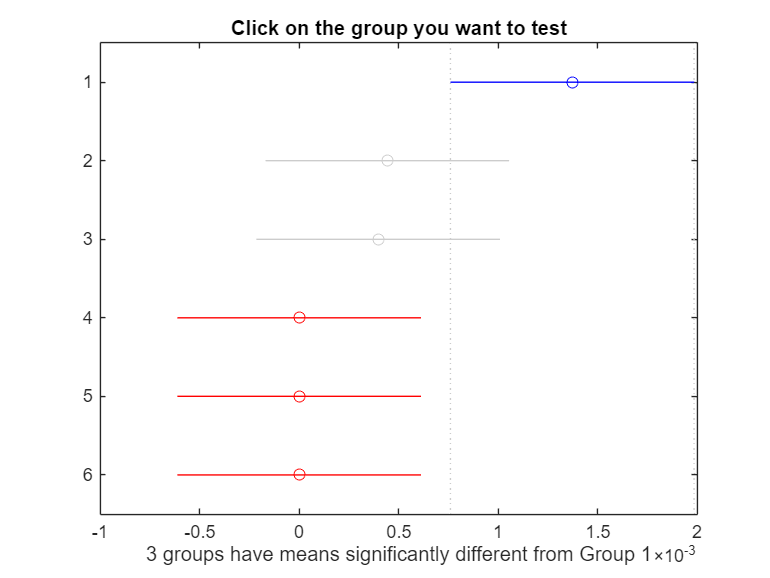

    Grupo1    Grupo2     Lower_CI         Diff       Upper_CI      PValue 
    ______    ______    ___________    __________    _________    ________

      1         2       -0.00029486    0.00092894    0.0021527     0.35243
      1         3       -0.00024919    0.00097462    0.0021984       0.266
      1         4        0.00014759     0.0013714    0.0025952    0.016844
      1         5        0.00014761     0.0013714    0.0025952    0.016842
      1         6        0.00014761     0.0013714    0.0025952    0.016841
      2         3        -0.0011781    4.5675e-05    0.0012695           1
      2         4       -0.00078135    0.00044245    0.0016663           1
      2         5       -0.00078133    0.00044247    0.0016663           1
      2         6       -0.00078133    0.0004


Test de ANOVA para RMSE


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


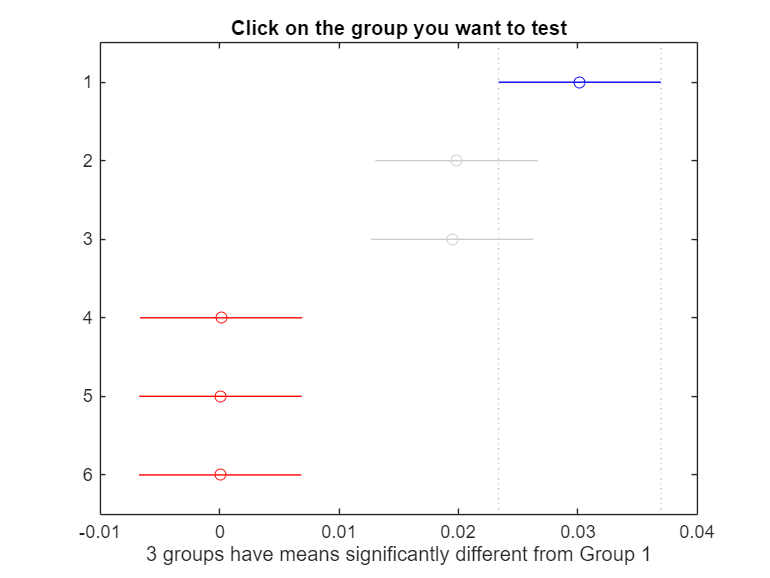

    Grupo1    Grupo2     Lower_CI        Diff       Upper_CI      PValue  
    ______    ______    __________    __________    ________    __________

      1         2       -0.0032843      0.010309    0.023903       0.35418
      1         3       -0.0029134       0.01068    0.024274       0.28859
      1         4         0.016424      0.030017    0.043611    1.3951e-07
      1         5         0.016482      0.030076     0.04367    1.3278e-07
      1         6         0.016508      0.030102    0.043695    1.2994e-07
      2         3        -0.013223    0.00037093    0.013965             1
      2         4        0.0061142      0.019708    0.033302      0.000644
      2         5        0.0061727      0.019766     0.03336    0.00061563
      2         6        0.0061984      0.019


Test de ANOVA para MAE


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


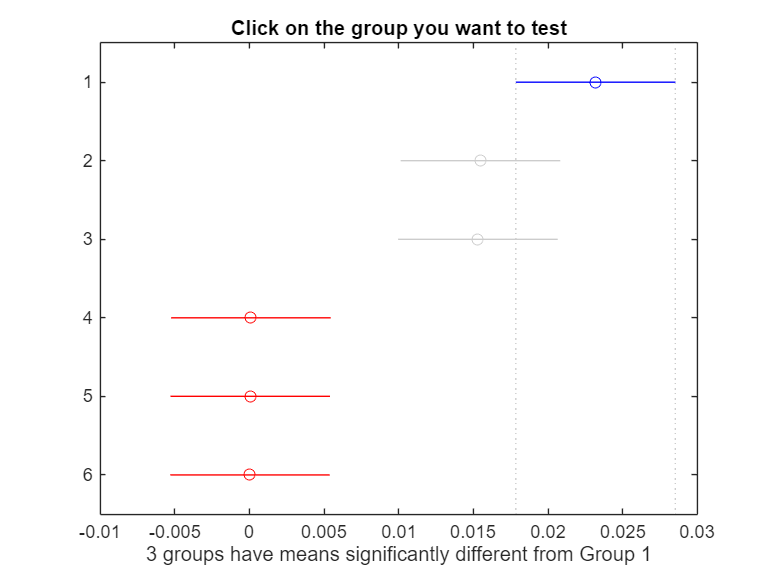

    Grupo1    Grupo2     Lower_CI        Diff       Upper_CI      PValue  
    ______    ______    __________    __________    ________    __________

      1         2       -0.0029774     0.0077076    0.018393       0.46438
      1         3       -0.0028082     0.0078768    0.018562       0.41402
      1         4         0.012391      0.023076    0.033761    2.4329e-07
      1         5         0.012437      0.023122    0.033807     2.316e-07
      1         6         0.012456      0.023141    0.033826    2.2688e-07
      2         3        -0.010516    0.00016922    0.010854             1
      2         4        0.0046837      0.015369    0.026054    0.00072565
      2         5        0.0047296      0.015415      0.0261    0.00069387
      2         6        0.0047488      0.015

% Lista de métricas a evaluar
metricNames = {'MSE', 'RMSE', 'MAE'};

% Aplicar ANOVA para cada métrica
for m = 1:numel(metricNames)
    metricName = metricNames{m};

    % Extraer la métrica correspondiente (ya es fold x modelos)
    metricData = metricsNN_DATOS2_1.(metricName);
    numFolds = size(metricData,1);
    numModels = size(metricData,2);

    y = metricData(:);
    group = repelem(1:numModels, numFolds)';

    % Aplicar test de ANOVA
    [p,~,stats] = anova1(y, group, 'off');  % No muestra la figura automáticamente

    fprintf('\nTest de ANOVA para %s\n', metricName);
    fprintf('P-valor: %.4f\n', p);

    if p < 0.05
        fprintf('Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...\n');
        figure;
        title(sprintf('Comparaciones múltiples para %s', metricName));
        [c,~,~,gnames] = multcompare(stats, 'CType', 'bonferroni');
        disp(array2table(c, 'VariableNames', {'Grupo1', 'Grupo2', 'Lower_CI', 'Diff', 'Upper_CI', 'PValue'}));
    else
        fprintf('No se encontraron diferencias significativas entre los modelos para %s.\n', metricName);
    end
end

Hay diferencias significativas entre los NN con distintos algoritmos, por lo que el modelo seleccionado sería el NN4 (algoritmo trainlm y nº neuronas 5).

Ahora comprobamos si existen diferencias entre los dos modelos que hemos escogido con distinto tamaño de ventana.

datos1_NN4 = struct('MSE', metricsNN_DATOS1_1.MSE(:,4), ...
                    'RMSE', metricsNN_DATOS1_1.RMSE(:,4), ...
                    'MAE', metricsNN_DATOS1_1.MAE(:,4));

datos2_NN4 = struct('MSE', metricsNN_DATOS2_1.MSE(:,4), ...
                    'RMSE', metricsNN_DATOS2_1.RMSE(:,4), ...
                    'MAE', metricsNN_DATOS2_1.MAE(:,4));

Test de Wilcoxon

% Test de Wilcoxon para MSE
[p_MSE, ~, ~] = signrank(datos1_NN4.MSE, datos2_NN4.MSE);
fprintf('MSE: p = %.4f', p_MSE);

MSE: p = 0.0488


% Test de Wilcoxon para RMSE
[p_RMSE, ~, ~] = signrank(datos1_NN4.RMSE, datos2_NN4.RMSE);
fprintf('RMSE: p = %.4f', p_RMSE);

RMSE: p = 0.0645


% Test de Wilcoxon para MAE
[p_MAE, ~, ~] = signrank(datos1_NN4.MAE, datos2_NN4.MAE);
fprintf('MAE: p = %.4f', p_MAE);

MAE: p = 0.0488

Está claro que el modelo con un tamaño de ventana de 5 es mejor para predecir valores. Ya que 2 de las 3 métricas presentan una disminución estadísticamente significativas respecto al modelo entrenado con un tamaño de ventana de 10.

Entrenamiento sobre todo el conjunto de datos con el mejor modelo (tamaño de ventana: 5, algoritmo 'trainlm')

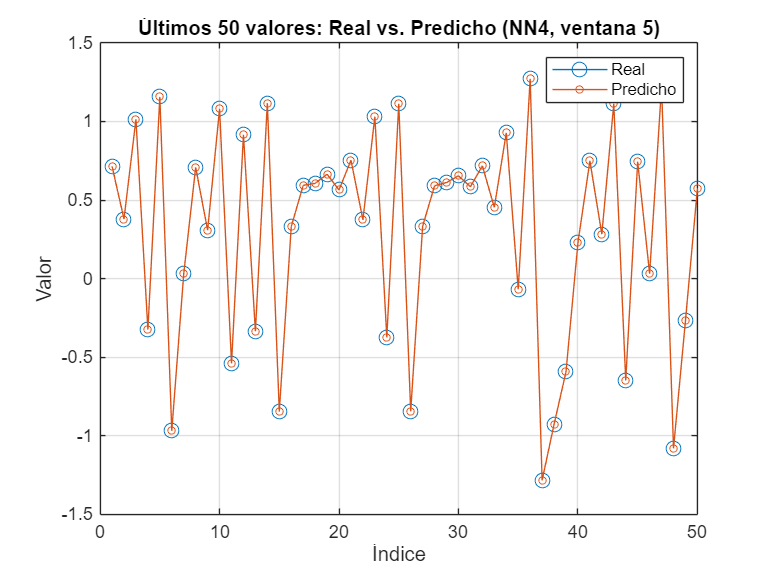

% === PREDICCIÓN CON LA MEJOR RED NEURONAL (NN4) ===

% Últimos 50 valores reales
x_last50_real = x(end-49:end);

% Generar todos los conjuntos con ventana tamaño 5
[INPUTS1_full, OUTPUTS1_full] = slidingwindow(x, 5);

% Excluir del entrenamiento las últimas 50 ventanas y sus salidas
num_total = size(INPUTS1_full, 1);
idx_train = 1:(num_total - 50);
idx_test = (num_total - 49):num_total;

X_train = INPUTS1_full(idx_train, :);
Y_train = OUTPUTS1_full(idx_train);
X_test = INPUTS1_full(idx_test, :);
Y_test = OUTPUTS1_full(idx_test);

% Crear y entrenar la mejor red neuronal (NN4: 5 neuronas, trainlm)
best_nn = fitnet(5, 'trainlm');
best_nn.trainParam.showWindow = false;
best_nn.divideParam.trainRatio = 0.8;
best_nn.divideParam.valRatio = 0.2;
best_nn.divideParam.testRatio = 0;

% Entrenar solo con los datos permitidos
best_nn = train(best_nn, X_train', Y_train');

% Predecir las últimas 50 salidas (no vistas durante el entrenamiento)
Y_pred = best_nn(X_test')';

% === VISUALIZACIÓN ===
figure;
plot(1:50, Y_test, '-o', 'MarkerSize', 8, 'DisplayName', 'Real');
hold on;
plot(1:50, Y_pred, '-o', 'MarkerSize', 4, 'DisplayName', 'Predicho');
title('Últimos 50 valores: Real vs. Predicho (NN4, ventana 5)');
xlabel('Índice');
ylabel('Valor');
legend;
grid on;
hold off;


% (Opcional) RMSE de las últimas 50 predicciones
rmse_nn4 = sqrt(mean((Y_test - Y_pred).^2));
fprintf('RMSE en las últimas 50 muestras (NN4): %.4f\n', rmse_nn4);

RMSE en las últimas 50 muestras (NN4): 0.0001


Por último comparamos los resultados entre el modelo elegido de NN y de SVM

datos1_NN4 = struct('MSE', metricsNN_DATOS1_1.MSE(:,4), ...
                    'RMSE', metricsNN_DATOS1_1.RMSE(:,4), ...
                    'MAE', metricsNN_DATOS1_1.MAE(:,4));

datos1_SVM4 = struct('MSE', metricsSVM_DATOS1_1.MSE(:,4), ...
                    'RMSE', metricsSVM_DATOS1_1.RMSE(:,4), ...
                    'MAE', metricsSVM_DATOS1_1.MAE(:,4));

% Test de Wilcoxon para MSE
[p_MSE, ~, ~] = signrank(datos1_NN4.MSE, datos1_SVM4.MSE);
fprintf('MSE: p = %.4f', p_MSE);

MSE: p = 0.0020


% Test de Wilcoxon para RMSE
[p_RMSE, ~, ~] = signrank(datos1_NN4.RMSE, datos1_SVM4.RMSE);
fprintf('RMSE: p = %.4f', p_RMSE);

RMSE: p = 0.0020


% Test de Wilcoxon para MAE
[p_MAE, ~, ~] = signrank(datos1_NN4.MAE, datos1_SVM4.MAE);
fprintf('MAE: p = %.4f', p_MAE);

MAE: p = 0.0020

Hay diferencias estadísticamente significativas para las 3 métricas. Por ello, nos quedamos con la NN.